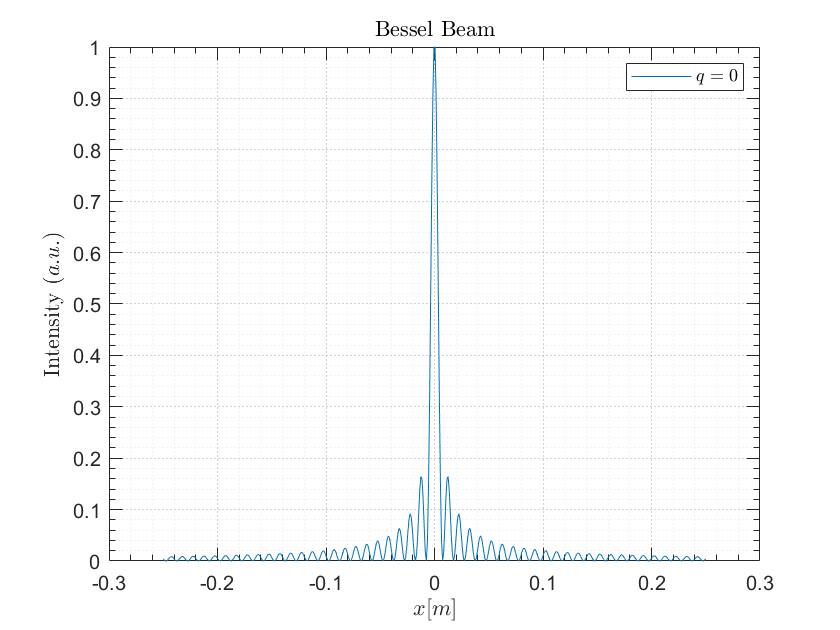

% Parameters
L = 500e-3;      % Physical size of the grid (10 mm)
N = 500;        % Number of grid points
k_r = 2*pi*50;  % Transverse wavevector (50 cycles per mm)

% Create Cartesian grid
x = linspace(-L/2, L/2, N);
y = linspace(-L/2, L/2, N);
[X, Y] = meshgrid(x, y);

% Calculate radial distance
r = sqrt(X.^2 + Y.^2);

% Compute the Bessel beam
E = besselj(0, k_r * r);  % Zeroth-order Bessel function

% Normalize the intensity for visualization
I = abs(E).^2;
I = I / max(I(:));
Ix = I(N/2, :);

% Plot the Bessel beam intensity
figure;
plot(x, Ix);
title("Bessel Beam", "Interpreter","latex")
legend("$q = 0$", "Interpreter","latex")
xlabel("$x [m]$", "Interpreter","latex")
ylabel("Intensity $(a.u.)$", "Interpreter","latex")
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

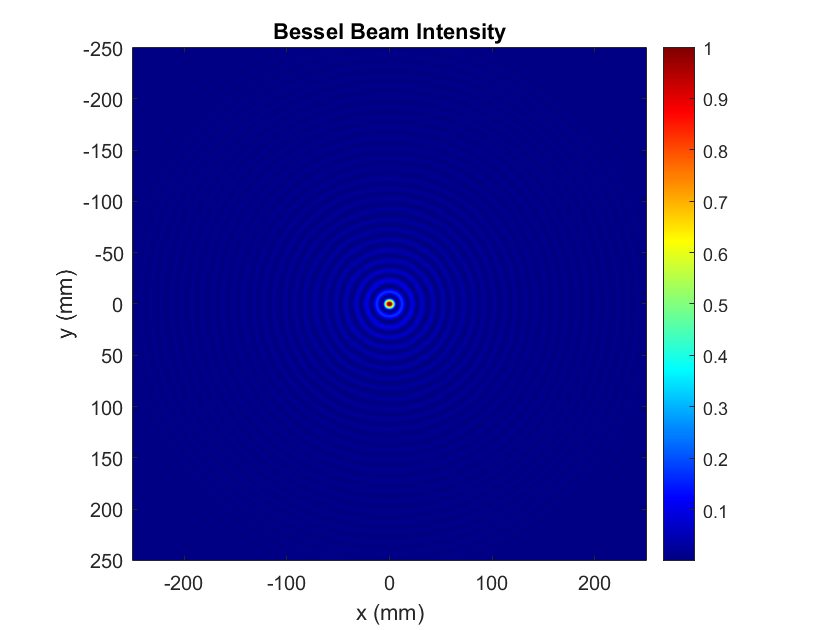


figure;
imagesc(x*1e3, y*1e3, I);
axis image;
colormap("jet");
colorbar;
xlabel('x (mm)');
ylabel('y (mm)');
title('Bessel Beam Intensity');